%CS170 Project 2 Live Script File
addpath('E:\Winter2021\CS170\Project2\FeatureSelectionWithNN')

datafile = 'CS170_largetestdata__2.txt';
%datafile = 'CS170_SMALLtestdata__42.txt';
%datafile = 'CS170_small_special_testdata__95.txt';

%read data from file
data = readmatrix(datafile);

disp(['Reading Data Set from file "', datafile,'"' ]);

disp(['Read file of ',num2str(size(data,1)),' data points with ',num2str(size(data,2)-1),' features each.']);

%find best performing combination of features through Search
disp(['> Starting forward search <'])
tic;
[best_features_for , ordered_features_for, performances_for]= Forward_Search(data(:,2:size(data,2)),data(:,1));

----Accuracy: 0.744
--Considering adding feature 97
----Accuracy: 0.756
On level 90, added feature 71.
On level 91 of search tree
--Considering adding feature 9
----Accuracy: 0.75
--Considering adding feature 12
----Accuracy: 0.746
--Considering adding feature 15
----Accuracy: 0.75
--Considering adding feature 25
----Accuracy: 0.736
--Considering adding feature 50
----Accuracy: 0.762
--Considering adding feature 54
----Accuracy: 0.764
--Considering adding feature 75
----Accuracy: 0.74
--Considering adding feature 81
----Accuracy: 0.758
--Considering adding feature 93
----Accuracy: 0.758
--Considering adding feature 97
----Accuracy: 0.748
On level 91, added feature 54.
On level 92 of search tree
--Considering adding feature 9
----Accuracy: 0.74
--Considering adding feature 12
----Accuracy: 0.748
--Considering adding feature 15
----Accuracy: 0.756
--Considering adding feature 25
----Accuracy: 0.746
--Considering adding feature 50
----Accuracy: 0.762
--Considering adding feature 75
----Ac

toc;

Elapsed time is 5681.857275 seconds.




disp(['> Starting backward search <'])

> Starting backward search <


tic;
[best_features_back , ordered_features_back, performances_back]= Backward_Search(data(:,2:size(data,2)),data(:,1));

On level 1 of search tree
--Considering dropping feature 1
----Accuracy: 0.714
--Considering dropping feature 2
----Accuracy: 0.704
--Considering dropping feature 3
----Accuracy: 0.716
--Considering dropping feature 4
----Accuracy: 0.698
--Considering dropping feature 5
----Accuracy: 0.704
--Considering dropping feature 6
----Accuracy: 0.708
--Considering dropping feature 7
----Accuracy: 0.712
--Considering dropping feature 8
----Accuracy: 0.716
--Considering dropping feature 9
----Accuracy: 0.708
--Considering dropping feature 10
----Accuracy: 0.698
--Considering dropping feature 11
----Accuracy: 0.71
--Considering dropping feature 12
----Accuracy: 0.716
--Considering dropping feature 13
----Accuracy: 0.72
--Considering dropping feature 14
----Accuracy: 0.692
--Considering dropping feature 15
----Accuracy: 0.718
--Considering dropping feature 16
----Accuracy: 0.718
--Considering dropping feature 17
----Accuracy: 0.722
--Considering dropping feature 18
----Accuracy: 0.706
--Considering

toc;

Elapsed time is 5597.386119 seconds.


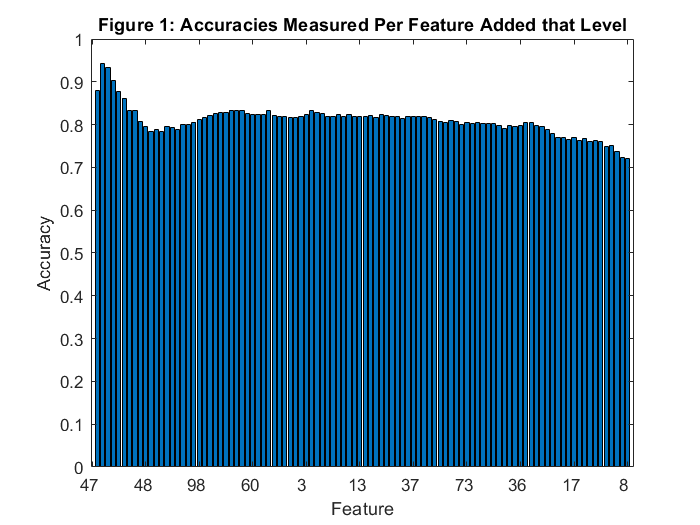

bar(performances_for)
hold on;

set(gca,'xticklabel',ordered_features_for);
title("Figure 1: Accuracies Measured Per Feature Added that Level");
xlabel('Feature');
ylabel('Accuracy');
hold off;

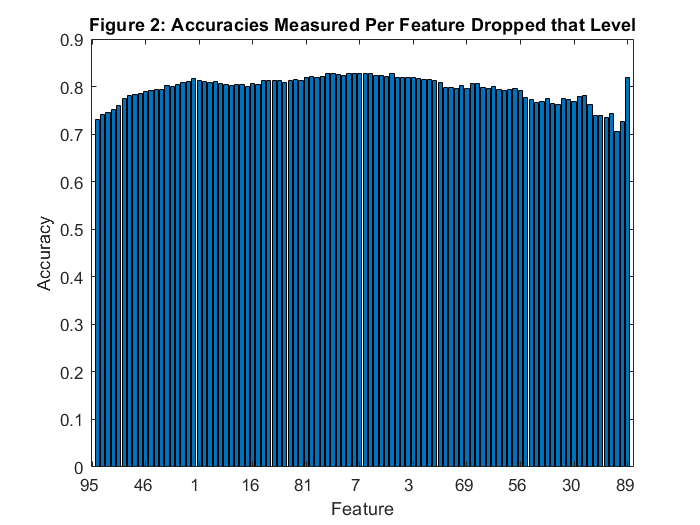


bar(performances_back)
hold on;

set(gca,'xticklabel',ordered_features_back);
title("Figure 2: Accuracies Measured Per Feature Dropped that Level");
xlabel('Feature');
ylabel('Accuracy');
hold off;

if max(performances_for) >= max(performances_back)
    best_features = best_features_for
    best_performance = max(performances_for)
else
    best_features = best_features_back
    best_performance = max(performances_back)
end

best_features =     47    48


best_performance = 0.9420


%data(:,best_features) = []
%[best_features , ordered_features, performances]= Forward_Search(data(:,2:size(data,2)),data(:,1))

%[best_features]



function [best_features, ordered_features, performances] = Backward_Search(data,class)
    best_feature_accuracies = [];
    current_set_of_features = 1:size(data,2);
    set_of_dropped_features = [];
    for i = 1:size(data,2)
        disp(['On level ',num2str(i),' of search tree']);
        feature_to_drop_at_this_level = [];
        best_so_far_accuracy = 0;
        
        for k = 1:size(data,2)
            if isempty(intersect(set_of_dropped_features,k))
                disp(['--Considering dropping feature ', num2str(k)]);
                accuracy = Leave_One_Out_Cross_Validation(data,class,setdiff(current_set_of_features,[set_of_dropped_features,k]));
                disp(['----Accuracy: ',num2str(accuracy)]);
                
                if accuracy > best_so_far_accuracy
                    best_so_far_accuracy = accuracy;
                    feature_to_drop_at_this_level = k;
                end
            end
        end
        set_of_dropped_features(i) = feature_to_drop_at_this_level;
        best_feature_accuracies(i) = best_so_far_accuracy;
        [~,ind] = find(current_set_of_features == feature_to_drop_at_this_level);
        current_set_of_features(ind) = [];
        disp(['On level ', num2str(i),', dropped feature ',num2str(feature_to_drop_at_this_level),'.']);

    end
    [~,ind] = max(best_feature_accuracies);
    ordered_features = set_of_dropped_features;
    performances = best_feature_accuracies;
    best_features = set_of_dropped_features;
    best_features(1:ind) = [];
end

function [best_features, ordered_features, performances] = Forward_Search(data,class)
    best_feature_accuracies = [];
    current_set_of_features = [];
    for i = 1:size(data,2)
        disp(['On level ',num2str(i),' of search tree']);
        feature_to_add_at_this_level = [];
        best_so_far_accuracy = 0;
        
        for k = 1:size(data,2)
            if isempty(intersect(current_set_of_features,k))
                disp(['--Considering adding feature ', num2str(k)]);
                accuracy = Leave_One_Out_Cross_Validation(data,class,[current_set_of_features,k]);
                disp(['----Accuracy: ',num2str(accuracy)]);
                
                if accuracy > best_so_far_accuracy
                    best_so_far_accuracy = accuracy;
                    feature_to_add_at_this_level = k;
                end
            end
        end
        current_set_of_features(i) = feature_to_add_at_this_level;
        best_feature_accuracies(i) = best_so_far_accuracy;
        disp(['On level ', num2str(i),', added feature ',num2str(feature_to_add_at_this_level),'.']);

    end
    [~,ind] = max(best_feature_accuracies);
    best_features = current_set_of_features(1:ind);
    ordered_features = current_set_of_features;
    performances = best_feature_accuracies;
end

%Performs data separatation and calls NN to find the total accuracies of
%of given set of features
function accuracy = Leave_One_Out_Cross_Validation(data,class,current_set_of_features)
    %edit to change cross validation group size    
    cross_cut = size(data,1);
    cut_size = size(data,1)/cross_cut;
    
    partial_acc = 0;
    for i = 1:cross_cut
        itt = (i-1)*cut_size + 1;
        itt2 = i*cut_size;
        test_data = data(itt:itt2,:);
        train_data = data(1:itt-1,:);data(itt2+1:size(data,1),:);
        test_class = class(itt:itt2);
        train_class = class(1:itt-1,:);data(itt2+1:size(data,1));
        partial_acc = partial_acc + NN(train_data,test_data,train_class,test_class,current_set_of_features);
    end
    accuracy = partial_acc/cross_cut;
end

%performs 1-Nearest Neighbor on given test set, comparing it to
function accuracy = NN(train_data,test_data,train_class, test_class, features) %k in this case is the amount of neighbors to consider
    sum_accuracy = 0;
    for i = 1:size(test_data,1) %for each point in the test set
        nearest_neighbor_class = 0;
        nearest_neighbor_dist = intmax;
        for y = 1:size(train_data,1) %compare it to the points in the train set
            dist = sqrt(sum((test_data(i,features) - train_data(y,features)).^2));
            if dist < nearest_neighbor_dist %and find the nearest point, record class and distance
                nearest_neighbor_class = train_class(y);
                nearest_neighbor_dist = dist;
            end
        end
        if nearest_neighbor_class == test_class(i) %if the nearest point classifies it right, it is accurate
            sum_accuracy = sum_accuracy +1;
        end
    end
    accuracy = sum_accuracy/size(test_data,1);
end